% Final Project
% Double Pendulum on Cart
% Chris Allum May 2021
clc
clearvars

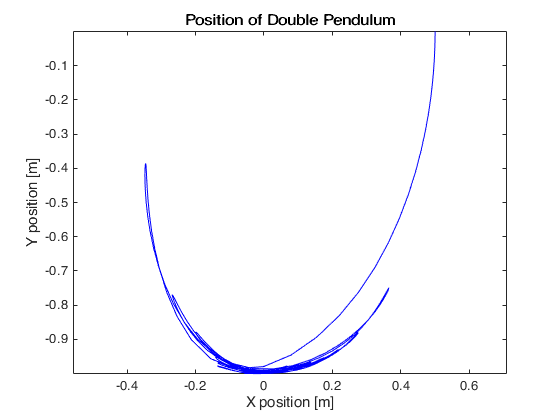

% system params
l1 = .5;
l2 = .5;
m1 = 1;
m2 = 1;
m3 = 1;
g = 9.8;

% initial position
x0 = -.5;
theta10 = pi/2;
theta20 = pi/2;

% initial velocity
dx0 = 0;
dtheta10 = 0;
dtheta20 = 0;

% pack initial conditions and params into vectors
params = [l1 l2 m1 m2 m3 g]';
init = [x0 dx0 theta10 dtheta10 theta20 dtheta20]';

% run simulation
[t,p] = simulation(params,init);

PlotPendulum(p,params)

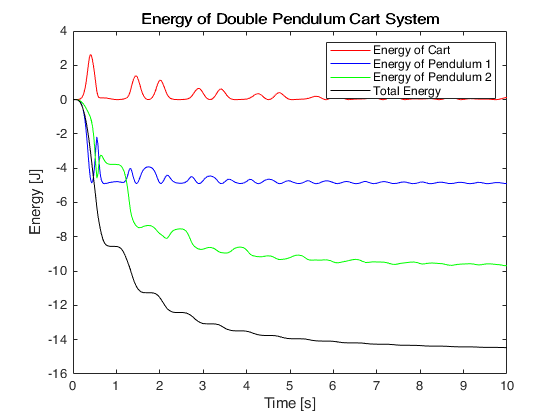

EnergyCalcs(t,p,params)

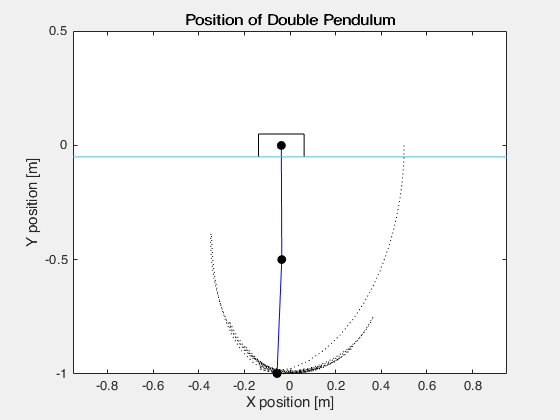

AnimatePendulum(p,params)

function [t,p] = simulation(params,init)
    
    % time span
    tspan = [0:.025:10];
    
    % simulation params, used in ODE funcs
    l1 = params(1);     % m
    l2 = params(2);     % m
    m1 = params(3);     % kg
    m2 = params(4);     % kg
    m3 = params(5);     % kg
    g = params(6);      % m/s^2
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        % cart force
        x  = p(1);
        dx = p(2);
        theta1 = p(3);
        dtheta1 = p(4);
        theta2 = p(5);
        dtheta2 = p(6);
        
        % drag
        B = .5;
        
        % pendulum velocities
        V1 = [dx 0];
        V2 = V1 + [l1*dtheta1*cos(theta1) l1*dtheta1*sin(theta1)];
        V3 = V2 + [l2*dtheta2*cos(theta2) l2*dtheta2*sin(theta2)];
        
        % velocity squared
        V1_sq = V1.*abs(V1);
        V2_sq = V2.*abs(V2);
        V3_sq = V3.*abs(V3);     
        
        q = [1 0 0 0 0 0 0 0;
             0 m1 0 0 0 0 -sin(theta1) 0;
             0 0 1 0 0 0 0 0;
             0 1 -l1*dtheta1*sin(theta1) l1*cos(theta1) 0 0 1/m1*sin(theta1) -1/m1*sin(theta2);
             0 0 0 0 1 0 0 0;
             0 0 l1*dtheta1*cos(theta1) l1*sin(theta1) 0 0 -1/m2*cos(theta1) 1/m2*cos(theta2);
             0 1 -l1*dtheta1*sin(theta1) l1*cos(theta1) -l2*dtheta2*sin(theta2) l2*cos(theta2) 0 1/m3*sin(theta2);
             0 0 l1*dtheta1*cos(theta1) l1*sin(theta1) l2*dtheta2*cos(theta2) l2*sin(theta2) 0 -1/m3*cos(theta2)];



         r = [dx; 
             -B*V1_sq(1); 
             dtheta1; 
             -B/m2*V2_sq(1); 
             dtheta2; 
             -g - B/m2*V2_sq(2); 
             -B/m3*V3_sq(1); 
             -g - B/m3*V3_sq(2)];

        z = (q\r)';
        
        dx = z(1);
        ddx = z(2);
        dtheta1= z(3);
        ddtheta1 = z(4);
        dtheta2 = z(5);
        ddtheta2 = z(6);

        % pack ODEs into column vector
        dpdt = [dx ddx dtheta1 ddtheta1 dtheta2 ddtheta2]';
    end

end

function PlotPendulum(p,params)
    % create r1, r2, r3 vectors
    x = p(:,1);
    theta1 = p(:,3);
    theta2 = p(:,5);
    l1 = params(1);     % m
    l2 = params(2);     % m
    
    cart = [x zeros(length(x),1)];   % cart vector
    pendulum1 = [l1*sin(theta1) -l1*cos(theta1)];   % m1 pendulum
    pendulum2 = [l2*sin(theta2) -l2*cos(theta2)];   % m2 pendulum
    pendulum_tot = cart + pendulum1 + pendulum2;
    
    figure
    plot(pendulum_tot(:,1),pendulum_tot(:,2),"-b")
    xlim([min(pendulum_tot(:,1)) max(pendulum_tot(:,1))])
    axis equal
    title("Position of Double Pendulum")
    xlabel("X position [m]")
    ylabel("Y position [m]")
    
end

function AnimatePendulum(p,params)
    % create r1, r2, r3 vectors
    cart_x = p(:,1);
    theta1 = p(:,3);
    theta2 = p(:,5);
    l1 = params(1);     % m
    l2 = params(2);     % m
    
    cart = [cart_x zeros(length(cart_x),1)];   % cart vector
    pendulum1 = [l1*sin(theta1) -l1*cos(theta1)];   % m1 pendulum
    pendulum2 = [l2*sin(theta2) -l2*cos(theta2)];   % m2 pendulum
    pendulum_tot = cart + pendulum1 + pendulum2;
    
    h = figure("Visible","on");
    filename = '9.gif';
    for point = 1:length(pendulum_tot)
        
        % create pendulum arms vectors
        pendulum_arms_x = [cart_x(point) pendulum1(point,1)+cart(point,1);
                           pendulum1(point,1)+cart(point,1) pendulum_tot(point,1)];
        pendulum_arms_y = [0 pendulum1(point,2);
                           pendulum1(point,2) pendulum_tot(point,2) ];
        
        % plot pendulum arms
        plot(pendulum_arms_x,pendulum_arms_y,"-b","MarkerSize",5), hold on
        
        % create pendulum mass points
        x = [pendulum1(point,1)+cart(point,1) pendulum_tot(point,1)];
        y = [pendulum1(point,2) pendulum_tot(point,2)];

        % plot pendulum mass points
        plot(x,y,"ok",'MarkerFaceColor','k')
        
        % plot pendulum origin
        plot(cart(point,1),0,"ok",'MarkerFaceColor','k')
        
        % create trail points
        trail_x = pendulum_tot(1:point,1);
        trail_y = pendulum_tot(1:point,2);
        
        % plot trail
        plot(trail_x,trail_y,":k","MarkerSize",.1)
        
        % add rectangle
        rectangle("Position",[cart(point,1)-.1 -.05 .2 .1])
        
        % add path
        fplot(@(x) -.05 + 0.*x), hold off
        
        xlim([min(pendulum_tot(:,1)) max(pendulum_tot(:,1))])

        ylim([-(l1+l2) .5])
        axis equal

        
        xlabel("X position [m]")
        ylabel("Y position [m]")
        title("Position of Double Pendulum")
        
        drawnow

        
        % Capture the plot as an image 
        frame = getframe(h); 
        im = frame2im(frame); 
        [imind,cm] = rgb2ind(im,256); 
        % Write to the GIF File 
        if point == 1 
            imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
        else 
            imwrite(imind,cm,filename,'gif',"DelayTime",0.07,'WriteMode','append'); 
        end
    end
end

function EnergyCalcs(t,p,params)
    % params
    l1 = params(1);     % m
    l2 = params(2);     % m
    m1 = params(3);     % kg
    m2 = params(4);     % kg
    m3 = params(5);     % kg
    g = params(6);      % m/s^2
    
    % motion
    cart_x = p(:,1);      % m
    cart_dx = p(:,2);     % m/2
    theta1 = p(:,3);      % rad
    dtheta1 = p(:,4);     % rad/s
    theta2 = p(:,5);      % rad
    dtheta2 = p(:,6);     % rad/s
    
    % cart
    cart_V = [cart_dx zeros(length(cart_dx),1)];
    
    cart_KE = 0.5*m1.*vecnorm(cart_V')'.^2;
    
    % pendulum1
    pendulum1_PE = -m2*g*l1*cos(theta1);
    
    pendulum1_V = cart_V + [l1.*dtheta1.*cos(theta1) l1.*dtheta1.*sin(theta1)];
    pendulum1_KE = 0.5*m2.*vecnorm(pendulum1_V')'.^2;
    
    pendulum1_Tot = pendulum1_PE + pendulum1_KE;
    
    % pendulum2
    pendulum2_PE = -m3*g*(l1*cos(theta1) + l2*cos(theta2));
    
    pendulum2_V = pendulum1_V + [l2.*dtheta2.*cos(theta2) l2.*dtheta2.*sin(theta2)];
    pendulum2_KE = 0.5*m3.*vecnorm(pendulum2_V')'.^2;
    
    pendulum2_Tot = pendulum2_PE + pendulum2_KE;
    
    % total
    Energy_tot = cart_KE + pendulum1_Tot + pendulum2_Tot;
    
    figure

    plot(t,cart_KE,"-r"), hold on 
    plot(t,pendulum1_Tot,"-b")
    plot(t,pendulum2_Tot,"-g")
    plot(t,Energy_tot,"-k")
    
    title("Energy of Double Pendulum Cart System")
    xlabel("Time [s]")
    ylabel("Energy [J]")
    legend(["Energy of Cart","Energy of Pendulum 1","Energy of Pendulum 2","Total Energy"],"Location","northeast")
    
end